clear
syms s
k1 = 150;
k2 = 700;
b1 = 15;
b2 = 3;
M1 = 5;
M2 = 20;

A = [0, 0, 1, 0;
    0, 0, 0, 1;
    -k1/M1, k1/M1, -b1/M1, b1/M1;
    k1/M2, -(k1+k2)/M2, b1/M2, -(b1+b2)/M2];
B=[0; 0; 1/M1; 0];
C=[1, 0, 0, 0]; % y(t) = p(t)
D= 0;
Phi = inv(s*eye(4)-A)

$$Phi = \begin{array}{l} \left(\begin{array}{cccc} \frac{20\,s^{3}+78\,s^{2}+859\,s+2100}{\sigma_{1}} & \frac{30\,\left(20\,s-67\right)}{\sigma_{1}} & \frac{2\,\left(10\,s^{2}+9\,s+425\right)}{\sigma_{1}} & \frac{60\,\left(s+10\right)}{\sigma_{1}}\\ \frac{150\,s}{\sigma_{1}} & \frac{20\,s^{3}+78\,s^{2}+609\,s+90}{\sigma_{1}} & \frac{15\,\left(s+10\right)}{\sigma_{1}} & \frac{20\,\sigma_{2}}{\sigma_{1}}\\ -\frac{30\,\left(20\,s^{2}+3\,s+700\right)}{\sigma_{1}} & -\frac{30\,\left(67\,s-20\,s^{2}\right)}{\sigma_{1}} & \frac{2\,\left(10\,s^{3}+9\,s^{2}+425\,s\right)}{\sigma_{1}} & \frac{60\,\left(s^{2}+10\,s\right)}{\sigma_{1}}\\ \frac{150\,s^{2}}{\sigma_{1}} & -\frac{50\,\left(17\,s^{2}+42\,s+420\right)}{\sigma_{1}} & \frac{15\,s\,\left(s+10\right)}{\sigma_{1}} & \frac{20\,s\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=20\,s^{4}+78\,s^{3}+1459\,s^{2}+2190\,s+21000\\ \sigma_{2}=s^{2}+3\,s+30 \end{array}$$

G = C*Phi*B

$$G = \frac{2\,\left(10\,s^{2}+9\,s+425\right)}{5\,\left(20\,s^{4}+78\,s^{3}+1459\,s^{2}+2190\,s+21000\right)}$$

sys = ss(A, B, C, D)

sys =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3    -30     30     -3      3
   x4    7.5  -42.5   0.75   -0.9
 
  B = 
        u1
   x1    0
   x2    0
   x3  0.2
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.


x0=[0.1, 0, 0, 0]

x0 =     0.1000         0         0         0


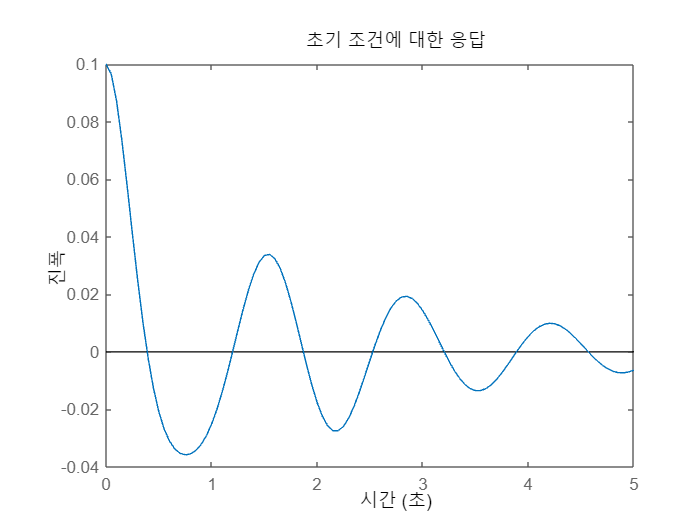

initial(sys, x0, 5)